number_of_simulations = 1000;
energies = zeros(number_of_simulations,1);
D = zeros(number_of_simulations, 1);

for ii = 1:number_of_simulations
    test;
    energies(ii) = H(num_iterations);
    D(ii) = decreasing;
    if energies(ii) >= 5
        q_bad = q0;
        break;
    end
end

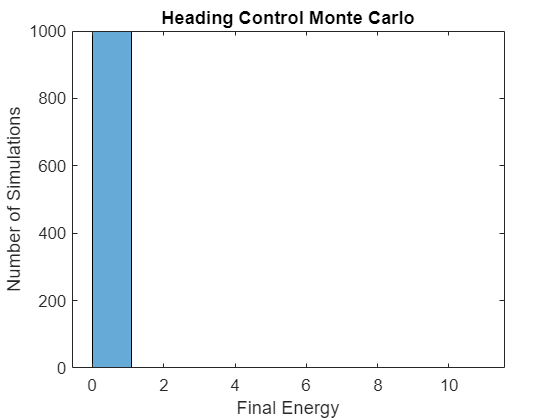

histogram(energies, 10);
plot_name = "cc_target_mc.png";
title("Heading Control Monte Carlo");
xlabel("Final Energy");
ylabel("Number of Simulations");
exportgraphics(gca, plot_name);

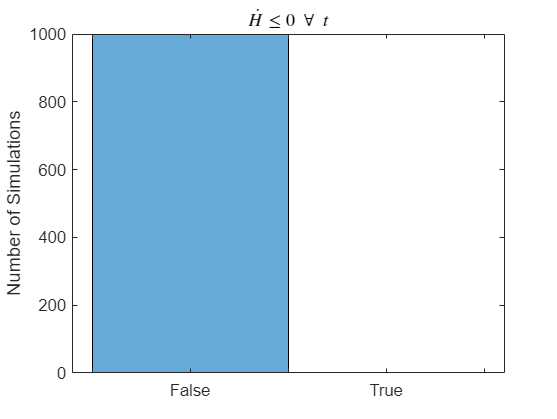

decreasing = [false, true, true];
histogram(D);
xticklabels(["", "False", "", "True"]);
plot_name = "number_of_increasing_sims_target_mc.png";
title("$\dot{H} \leq 0 \ \forall \ t$", Interpreter="latex");
ylabel("Number of Simulations");
exportgraphics(gca, plot_name);